# dtwm - Dynamic time warping, more

`dtwm` is a Matlab toolbox for dynamic time warping. The "m" stands for `MATLAB` or "more": the toolbox does more than the built-in Matlab function `dtw`, including:

- allowing for local slope constraints

- imposing global windows

- unconstrained endpoints

- calculation of local relative rate

The code for dynamic time warping is a port of the Python dtw package written by Toni Giorgino: 

T. Giorgino. Computing and Visualizing Dynamic Time Warping Alignments in R: The dtw Package. Journal of Statistical Software, v. 31, Issue 7, p. 1 - 24, aug. 2009. ISSN 1548-7660. doi:10.18637/jss.v031.i07. [http://www.jstatsoft.org/v31/i07/](http://www.jstatsoft.org/v31/i07/)

%NOTE: this script should be run with "DTWm" and all of its subdirectories on your path:
addpath(genpath('.'));

% this compiles the code for computing the cost matrix if necessary
if ~exist('dtwm_costmatrix'), mex dtwm_costmatrix.c; end

#### Input: a pair of signals

Here is a pair of signals that we wish to align. Each signal is one period of a cosine, but the frequencies differ: the first (blue) has a frequency of $2.0$ Hz and the second (orange) $1.0$ Hz. Both signals are sampled at a rate of $1000$ Hz.

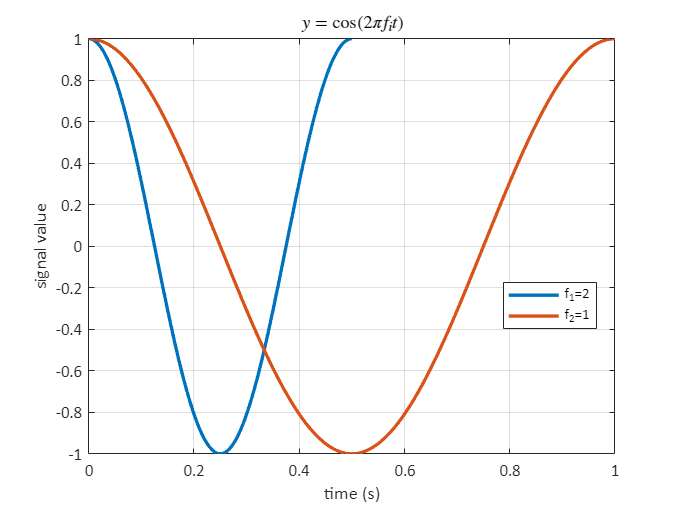

S = test_signals('example_1');
plot_signals(S);


X1 = S.X{1};
X2 = S.X{2};

#### Output: a warping path

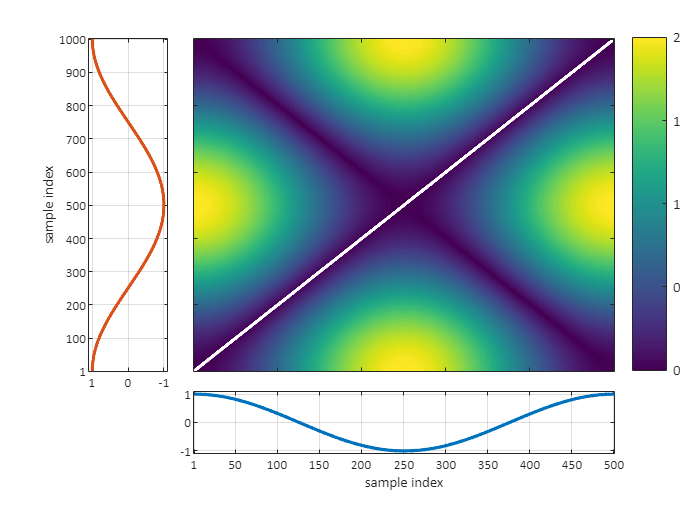

[wcurve,distance,info] = dtwm(X1,X2); %#ok<*ASGLU> 

%plots distance matrix and optimal warping path
plot_matrix_path(info,X1,X2);

The required inputs to `dtwm` can take one of two forms:

- two input signals, as above

- OR, a distance matrix (a.k.a. local cost matrix), as below:

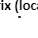

D = sqrt((X1-X2').^2); %euclidean distance

figure; imagesc(D); title('distance matrix (local cost matrix)');


[wcurve,distance,info] = dtwm(D);

The function `dtwm` returns up to three outputs:

- `wcurve`: the warping curve obtained from the dynamic time warping

- `distance`: the total distance associated with the optimal path through the local cost matrix

- `info`: a structure containing various information associated with the dynamic time warping, including the global cost matrix

### The warping curve

The warping produced by DTW is an ordered set of relations between the indices of the input signals. This set of binary relations will be informally referred to as a "mapping", and we will say that some index of one signal "maps" to one or more indices of the other. The indices are usually sample time indices, but do not have to be (for example, they could be one-dimensional spatial position indices). The indices of each of the two input signals are mapped (related) to one or more indices in the other. For example, the first 10 relations from the DTW above are:

first_10_relations = wcurve(:,1:10)

first_10_relations =      1     1     2     2     3     3     4     4     5     5
     1     2     3     4     5     6     7     8     9    10


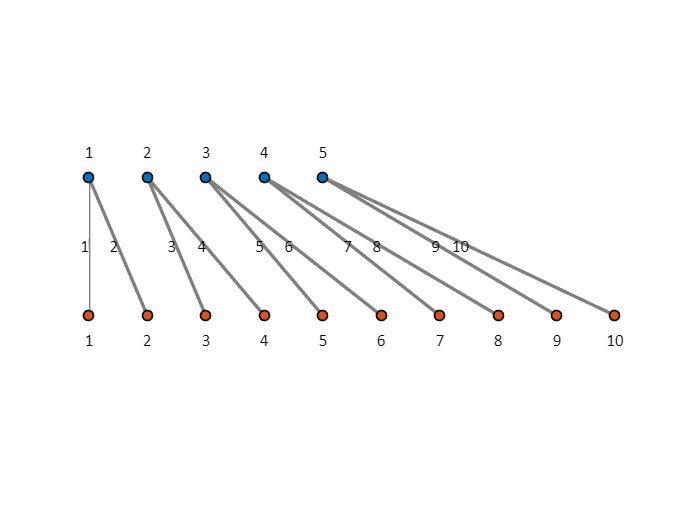


plot_mapping(wcurve(:,1:10));

In the figure above, the points correspond to the unique sample indices of the two input signals. The mappings are the lines connecting them. These are numbered according to their order in the map.

#### Aligned signals

The simplest and most common way to obtain the aligned signals is simply to index the original signals with the vectors of indices which comprise the mapping, i.e. 

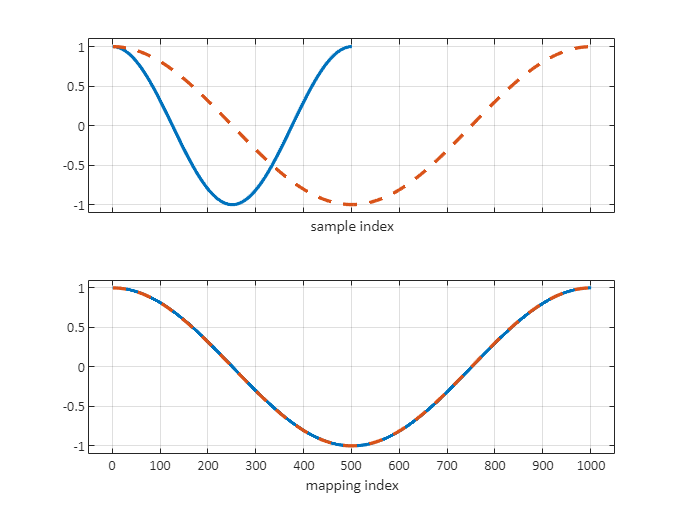

X1a = X1(wcurve(1,:));
X2a = X2(wcurve(2,:));

alignment_comparison(X1,X2,X1a,X2a);

Notice that the signals are now almost identical. The first signal (blue line) has been stretched so that it is aligned to the second signal (orange). This method of obtaining the aligned signals is an example of the *external reference frame* approach, a term which we explain below. To show why other methods might be useful, it is helpful to consider a different example...

#### An example with one-to-many and many-to-one mappings

Here is an example of two signals constructed to demonstrate an under-appreciated point about dynamic time warping: the algorithm adopts the point of view of an external observer who insists that each unique sample of both signals is included in the mapping.

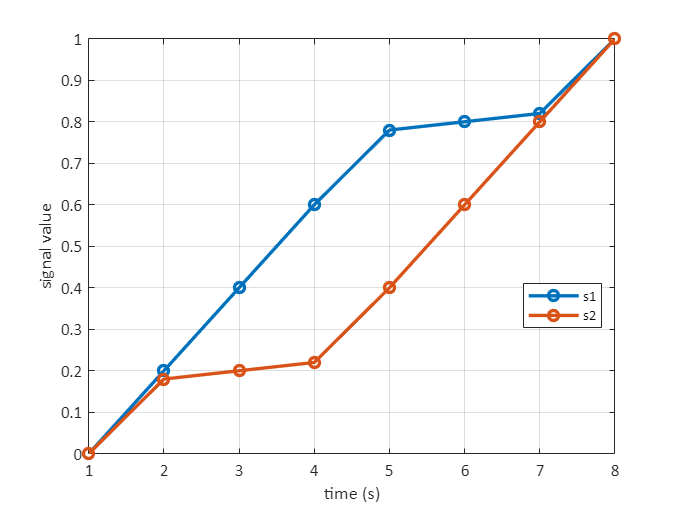

S = test_signals('alignment_example');
plot_signals(S);

DTW and warping curve:

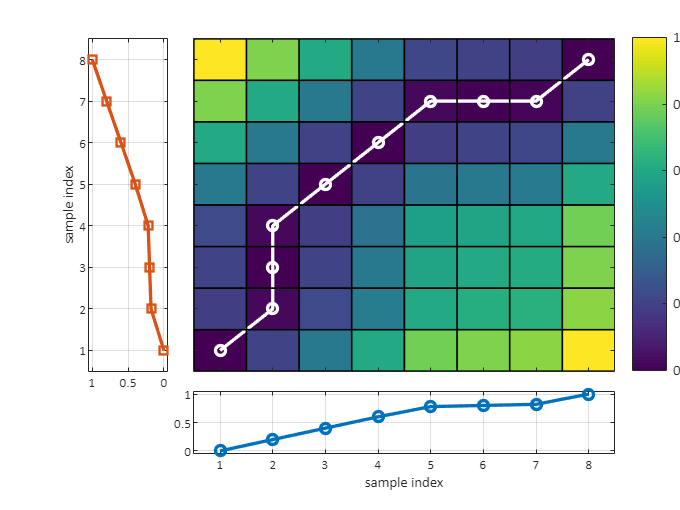

X1 = S.X{1};
X2 = S.X{2};

[wcurve,distance,info] = dtwm(X1,X2);

plot_matrix_path(info,X1,X2)

Notice in  this example that the second sample of $X_1$ maps to three consecutive samples of $X_2$, and conversely that the 5th, 6th, and 7th samples of $X_1$ map to the 7th sample of $X_2$:

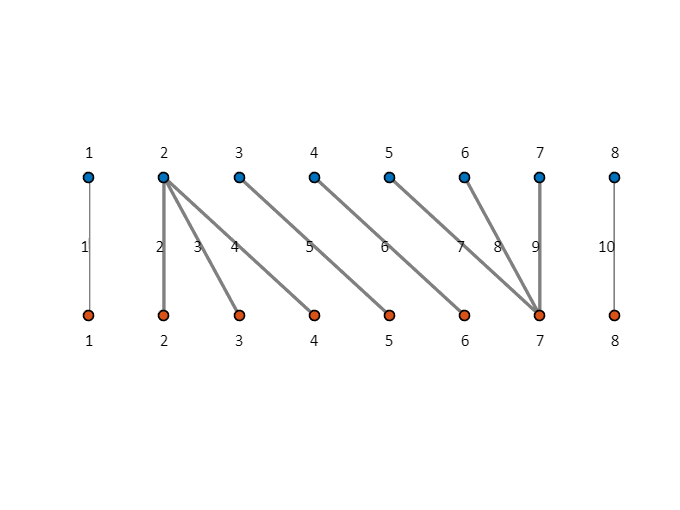

plot_mapping(wcurve)

#### Classification of alignment strategies

There are three types of alignment:

External reference frame

- expansive alignment

- compressive alignment

Signal reference frame

These three types of alignments are described in the paper and exemplified below.

#### Aligned signals: external reference frame; expansive alignment

Using an external reference frame approach to obtaining aligned signals, notice that the lengths of the aligned signals are longer than either of the original signals.

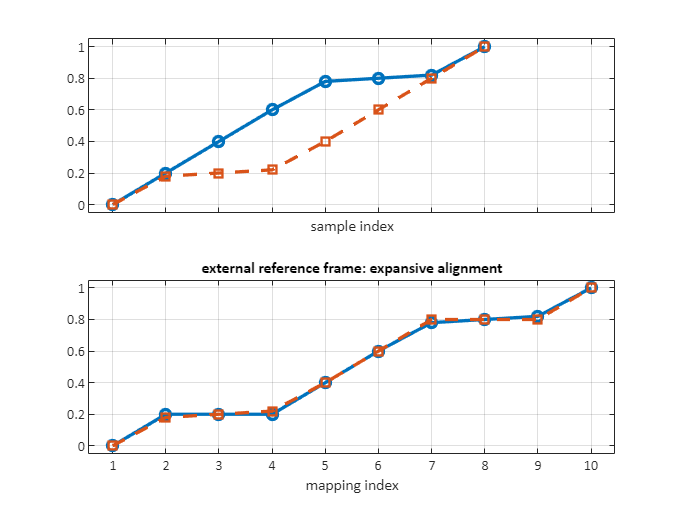

X1a = X1(wcurve(1,:));
X2a = X2(wcurve(2,:));

alignment_comparison(X1,X2,X1a,X2a);
title('external reference frame: expansive alignment');

When alignments are obtained from the external reference frame approach, their length will always be greater than or equal to the length of the longer of the two input signals. The reason for this is that the external reference frame approach to alignment by default treats one-to-many mappings (in either direction), as a slowing down of one signal relative to another; it thereby warps the signals by stretching them. It never "skips" indices of either signal; instead, it repeats them.

#### Aligned signals: external reference frame; compressive alignment

An alternative approach to obtaining the alignment is to treat all one-to-many mappings as a speeding up of one signal relative to the other. This warps the signals by compressing them:

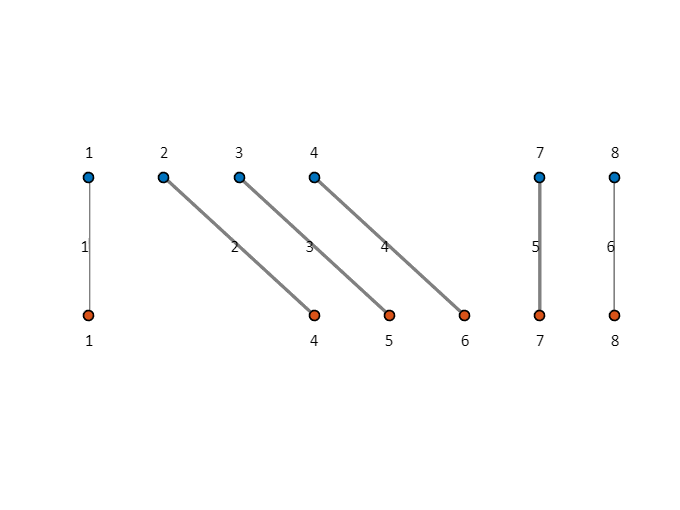

%only takes the last of mapping where there are one-to-many or many-to-one
%relations:
map_compress = wcurve(:,~any(diff([wcurve [0;0]],[],2)==0));

plot_mapping(map_compress);

In this case, the external observer converts all one-to-many mappings to one-to-one mappings. The compressive alignment never repeats indices; instead, it skips them.

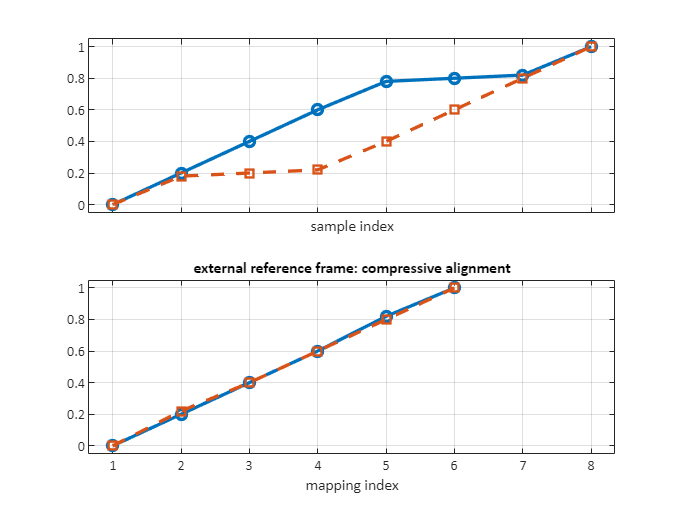

X1c = X1(map_compress(1,:));
X2c = X2(map_compress(2,:));

alignment_comparison(X1,X2,X1c,X2c);
title('external reference frame: compressive alignment');

#### Aligned signals: signal reference frames

An alternative approach is to adopt the point of view of one of the two signals. More specifically, we can imagine that there are two observers, who are traveling with the first and second signals, respectively, and we can imagine how they perceive the progression of states associated with the other observer. In this case, the aligned signals will be the same length as the whichever signal is associated with the chosen reference frame. For example, if we adopt the reference frame of the first observer who travels with the first signal (blue line):

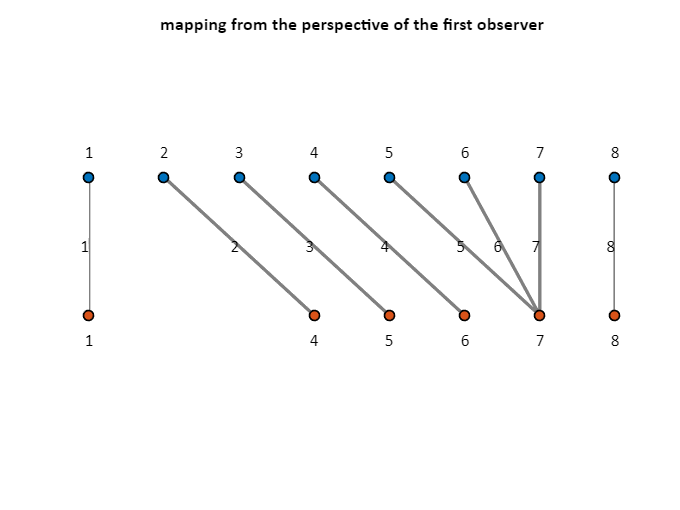

%unique sample indices associated with first signal:
ix1 = unique(wcurve(1,:));

%last sample of second signal that corresponds to each unique sample of
%first signal:
ix2 = arrayfun(@(c)wcurve(2,find(wcurve(1,:)==c,1,'last')),ix1);

plot_mapping([ix1; ix2])
title('mapping from the perspective of the first observer','Visible','on');

In this case (frame of reference of first observer), the aligned signals have the same length as the first signal.

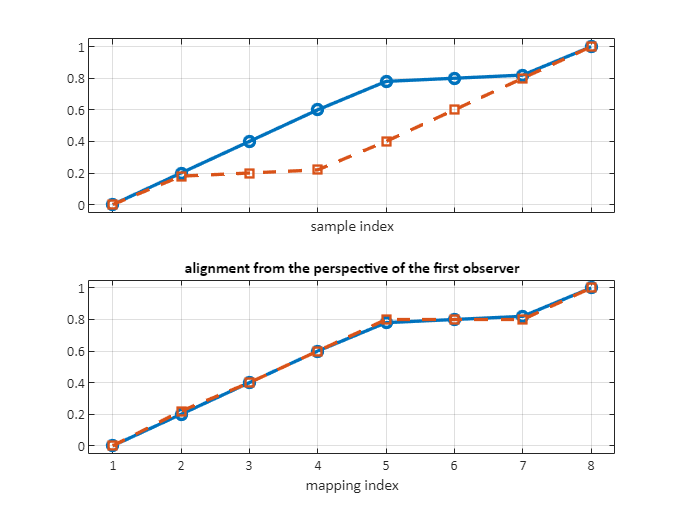

X1a_ref1 = X1;
X2a_ref1 = X2(ix2);

alignment_comparison(X1,X2,X1a_ref1,X2a_ref1);
title('alignment from the perspective of the first observer');

The observer traveling with the first signal, at sample index #2 (which they perceive as the "true" progression of states in their reference frame), sees that the second signal appears to slow down--it takes the other entity three steps to reach the same state. In contrast, during sample indices #5-#7, the observer sees that the entity associated with the second signal speeds up--what the observer experiences as three equal steps of time appears to be accomplished by the other entity in just one time step.

When we take the perspective of the second observer, the interpretation is reversed:

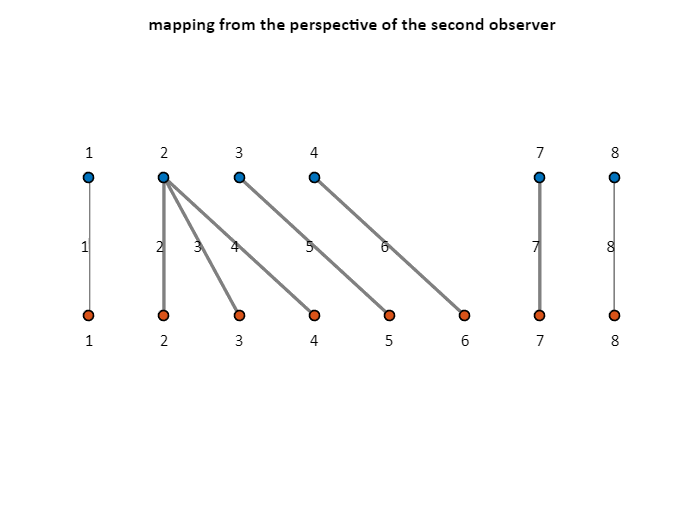

%unique sample indices associated with second signal:
ix2 = unique(wcurve(2,:));

%last sample of first signal that corresponds to each unique sample of
%second signal:
ix1 = arrayfun(@(c)wcurve(1,find(wcurve(2,:)==c,1,'last')),ix2);

plot_mapping([ix1; ix2])
title('mapping from the perspective of the second observer','Visible','on');

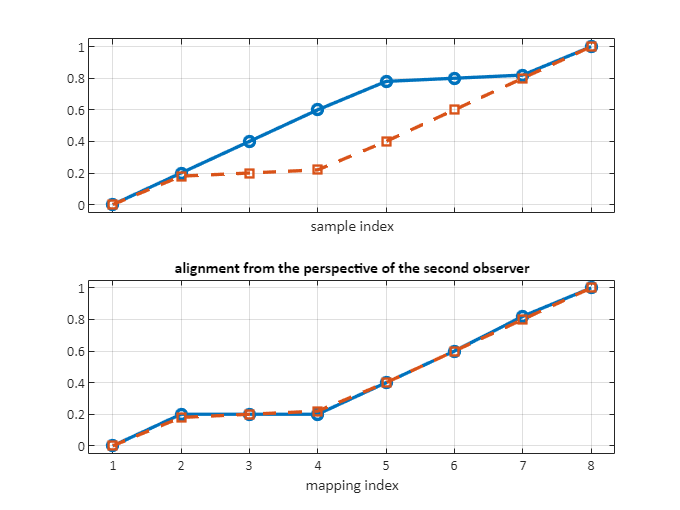


X1a_ref2 = X1(ix1);
X2a_ref2 = X2;

alignment_comparison(X1,X2,X1a_ref2,X2a_ref2);
title('alignment from the perspective of the second observer');

The observer traveling with the second signal, at sample indices #2-#4 (the "true" progression of states according to this observer), sees that the first signal appears to speed up--the other entity accomplishes this change in state in just one time step. In contrast, at sample index 7, the second observer sees that the entity associated with the first signal slows down--what the second observer experiences one step of time appears to take three time steps for the other entity to acheive.

#### Why frame of reference matters

The frame of reference of the alignment matters for several reasons. First, as we showed above, from an external reference frame is entirely ambiguous whether one-to-many mappings should be interpreted as the speeding up of one signal relative to the other (in which case the external observer slows down the signal, i.e., expansive alignment), or as the slowing down of one signal to the other (in which case the external observer speeds up the signal, i.e., compressive alignment).

It is also important to keep in mind the distinction between the relative progression of time between signals and the relative warping that is applied to align the signals. When one signal $X1$ slows down relative to $X2$, then either (from the perspective of $O2$) $X1$ must be sped up by the warping in order to align it to $X2$, or (from the perspective of $X1$) $X2$ must be slowed down by the warping. The external observer always chooses to slow down signals (stretching) or speed up signals (compression).

Adopting a particular signal as a frame of reference is also crucial when we analyze the rate of time progression in one signal relative to another--as in the method of local relative rate estimation that is performed by other functions in this toolbox. (See the livescript `lrr_method.mlx`).

### Distance measure

The second output of `dtwm` is the "normalized distance" between the signals. This normalized distance is the global cost associated with the optimal mapping.

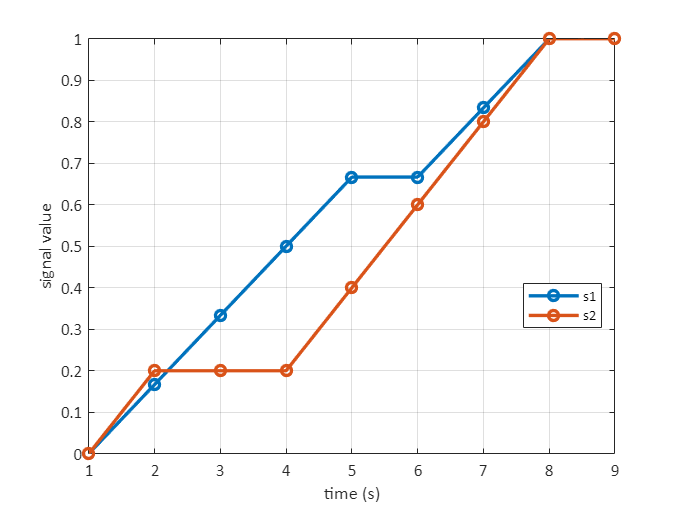

S = test_signals('alignment_example2');
plot_signals(S);


%these are the signals:
X1 = S.X{1};
X2 = S.X{2};

[wcurve,distance,info] = dtwm(X1,X2);

This is the "normalized distance":

distance

distance = 0.0373

The global cost matrix shows the accumulated local cost:

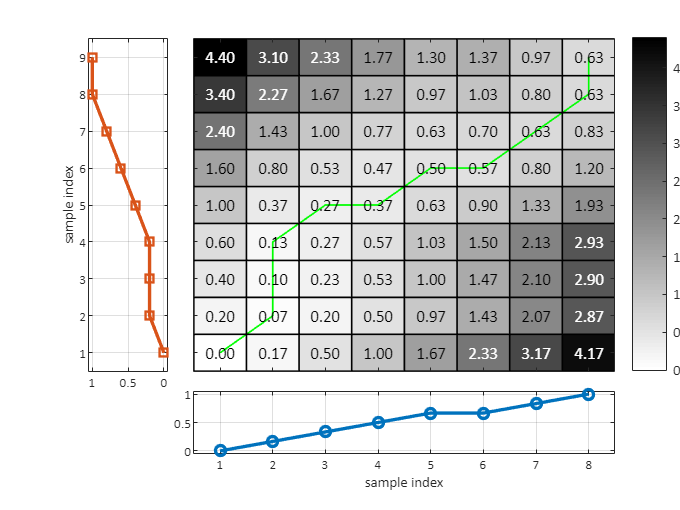

plot_matrix_path(info,X1,X2,'globalcost');

The normalization factor depends on the allowed step patterns (see *Algorithm details* below). In this case it is the sum of signal lengths:

avg_len = (length(X1)+length(X2));

The normalized distance is the global (cumulative) cost of the warping path divided by the normalization factor.

info.costMatrix(end,end)/avg_len

ans = 0.0373

In order to understand how the global cost matrix is calculated, it is necessary to understand how the algorithm works...

## Algorithm details

The following is a detailed description of how the algorithm works. It is not necessary to understand these details to use dynamic time warping.

#### Step pattern

A choice of a set of allowable step patterns is required to conduct dynamic time warping. The function `dtwm` by default uses a set of symmetric step patterns called "symmetric2":

pat = info.stepPattern

pat = struct with fields:
    pattern: 'symmetric2'
         mx: [6×4 double]
       norm: "N+M"


The rows of the matrix `stepPattern.mx` specify different parts of step patterns, in order. The step pattern that each part belongs to is specified in the first column. The first row of each pattern is the starting point of the pattern and has no cost (the cost value is specified as $-1$ and is ignored in the calculation). Each subsequent row for a given step pattern contains the next point associated with the pattern and the cost of the step from the previous point. 

STEPS = array2table(pat.mx,...
    'VariableNames',{'pattern id','delta row','delta col','cost'});

disp(STEPS);

    pattern id    delta row    delta col    cost
    __________    _________    _________    ____

        1             1            1         -1 
        1             0            0          2 
        2             0            1         -1 
        2             0            0          1 
        3             1            0         -1 
        3             0            0          1 



The components of step patterns can be visualized as in the examples below, where values on the horizontal and vertical axes are the indices of the cost matrix relative to a particular cell in the matrix (indices 0, 0). The term in parentheses in the labels of the patterns is the normalization factor. Some patterns are not normalized, such as `symmetric1`:

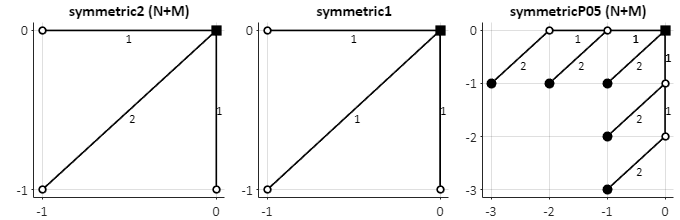

s = select_step_pattern({'symmetric2','symmetric1','symmetricP05'});

plot_steps(s);

The labels on the line segments are the costs associated with that part of the step pattern. For example, each part of the first step pattern of `symmetricP05` is a separate row of the matrix.

s = select_step_pattern({'symmetricP05'});

h = plot_steps(s);

components = s.mx(1:4,:)

components =      1     1     3    -1
     1     0     2     2
     1     0     1     1
     1     0     0     1


This is the first step pattern. The cost is the sum of the costs associated with each segment, i.e. $4$:

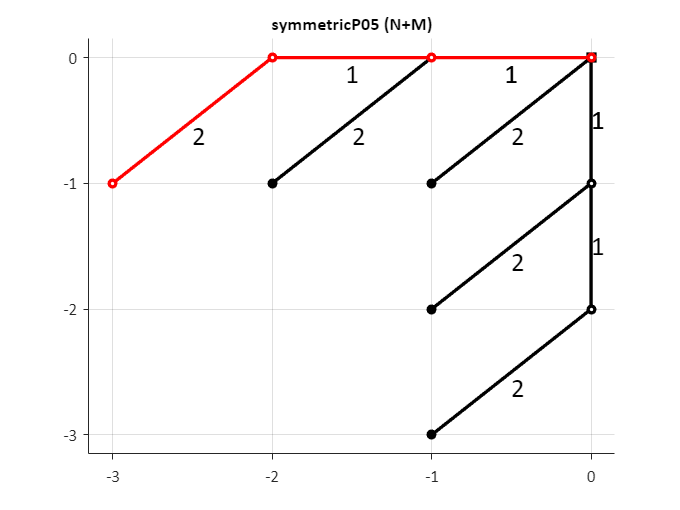

set(h.ph(1),'Color','r','ZData',2*ones(size(get(h.ph(1),'XData'))))

The toolbox function `select_step_pattern` provides many different step patterns and it is possible to define new ones.

s = select_step_pattern;
disp(s)

               pattern                     mx             norm   
    ______________________________    _____________    __________

    {'symmetric1'                }    { 6×4 double}    {0×0 char}
    {'symmetric2'                }    { 6×4 double}    {["N+M" ]}
    {'asymmetric'                }    { 6×4 double}    {["N"   ]}
    {'symmetricVelichkoZagoruyko'}    { 4×4 double}    {0×0 char}
    {'asymmetricItakura'         }    {10×4 double}    {0×0 char}
    {'symmetricP0'               }    { 6×4 double}    {["N+M" ]}
    {'asymmetricP0'              }    { 6×4 double}    {["N"   ]}
    {'asymmetricP0b'             }    { 5×4 double}    {["N"   ]}
    {'symmetricP05'              }    {16×4 double}    {["N+M" ]}
    {'asymmetricP05'             }    {16×4 double}    {["N"   ]}
    {'symmetricP1'               }    { 8×4 double}    {["N+M" ]}
    {'asymmetricP1'              }    {

### Classification of step patterns

There are several different classificatons of step patterns. For convenience the function `select_step_pattern` allows different classifications to be used.

#### Sakoe and Chiba

Sakoe and Chiba (1978) classify step patterns according to (a) whether they are symmetric and (b) according to a "slope constraint condition", defined as $P=n/m$, where a step that moves horizontally or vertically by $m$ indices must occur with at least $n$ diagonal steps. Note that $n$ and $m$ should not be confused with $N$ and $M$, which are the lengths of the input signals. Also note that "slope constraint condition" is not the same as "slope".

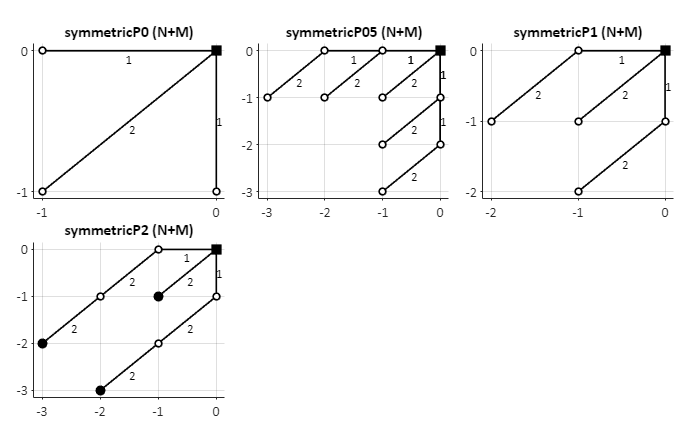

s = select_step_pattern({'symmetricP0','symmetricP05','symmetricP1','symmetricP2'});
plot_steps(s);

- `symmetricP0`: no slope constraint. 

- `symmetricP05`: slope constraint condition $P=1/2$ 

- `symmetricP1`: slope constraint condition $P=1$

- `symmetricP2`: slope constraint condition $P=2$

Note that `symmetricP0` is equivalent to the default pattern, `symmetric2`.

Each of the symmetric sets of patterns has a corresponding asymmetric version:

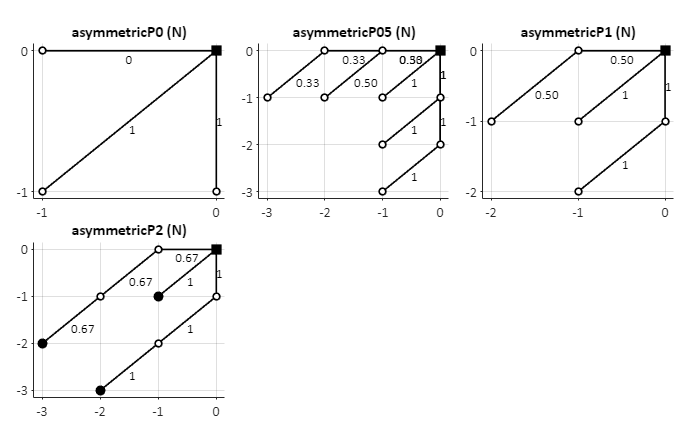

s = select_step_pattern({'asymmetricP0','asymmetricP05','asymmetricP1','asymmetricP2'});
plot_steps(s);

#### Rabiner and Juang

Rabiner and Juang (1993) step patterns are implemented via a function, `RabinerJuang_step_pattern`, which takes three arguments:

- local continuity constraint type: (1 - 7)

- slope weighting: ('a', 'b', 'c', 'd')

- smoothed: (`true` or `false`)

Comparison of slope weighting for constraint type 1:

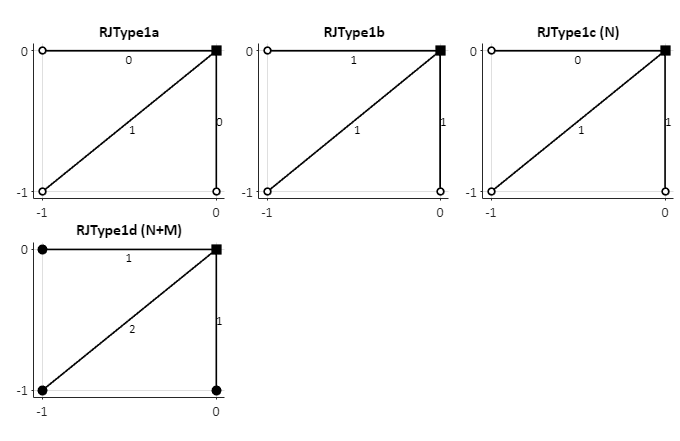

types = {'a','b','c','d'};
clear s;
for i=1:length(types)
    s(i) = RabinerJuang_step_pattern(1,types{i},false);
end

plot_steps(s);

Comparison of patterns 1-7 with slope weighting "d":

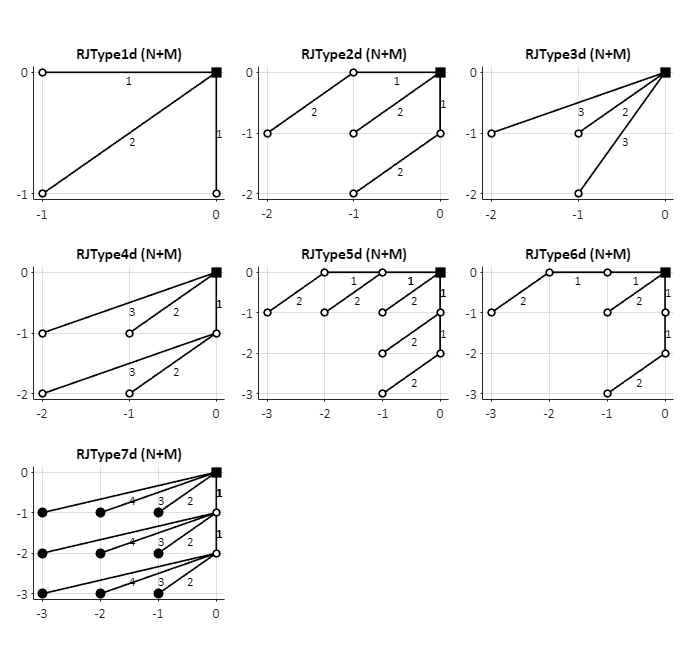

clear s;
for i=1:7
    s(i) = RabinerJuang_step_pattern(i,'d',false);
end

plot_steps(s);

Smoothed vs. unsmoothed weights:

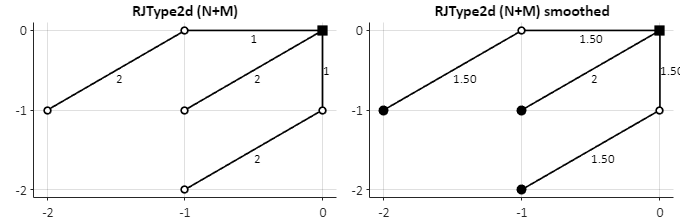

clear s;
s(1) = RabinerJuang_step_pattern(2,'d',false);
s(2) = RabinerJuang_step_pattern(2,'d',true);

h = plot_steps(s);
h{2}.titleh.String = [h{2}.titleh.String ' smoothed'];

#### Additional patterns

The Myers et al. (1980) classification is available. Giorgino (2009) describes this classification as obsoleted by the Rabiner & Juang one. Two other patterns are defined:

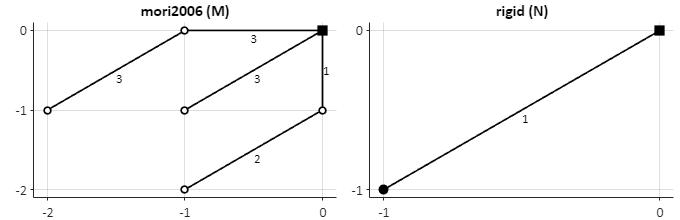

s = select_step_pattern({'mori2006','rigid'});
plot_steps(s);

- `mori2006`: Mori's asymmetric step-constrainted pattern

- `rigid`: fixed unitary slope; enforces no warping

Note that patterns `symmetricVelichkoZagoruyko` and `asymmetricItakura` are defined but not implemented because they require different algorithms.

#### Calculation of global cost matrix

The algorithm for calculation of the global cost matrix is implemented in C in `dtwm_costmatrix.c` and compiled to `dtwm_costmatrix.mexw64`. The compiled `mex` file is much faster than the implementation in Matlab, but the Matlab implement can be used if desired with the input `'use_mex', false, `which may be useful for understanding how the algorithm is implemented.

[wcurve,distance,info] = dtwm(X1,X2,'use_mex',false);

The global cost matrix calculation begins with a distance matrix--the distance between all pairs of signal values. The global cost matrix is initialized along with a matrix of steps taken:

The following code calculates the global cost:

To understand how this works, let's examine how the cost matrix gets updated for each step. We'll only take the first four signal values just to simplify the illustration. Each panel of the figure below shows the global cost matrix after it has been updated. Note that the updates increase from bottom to top and then from left to right; similarly, the rows of the cost matrix increase from bottom to top.

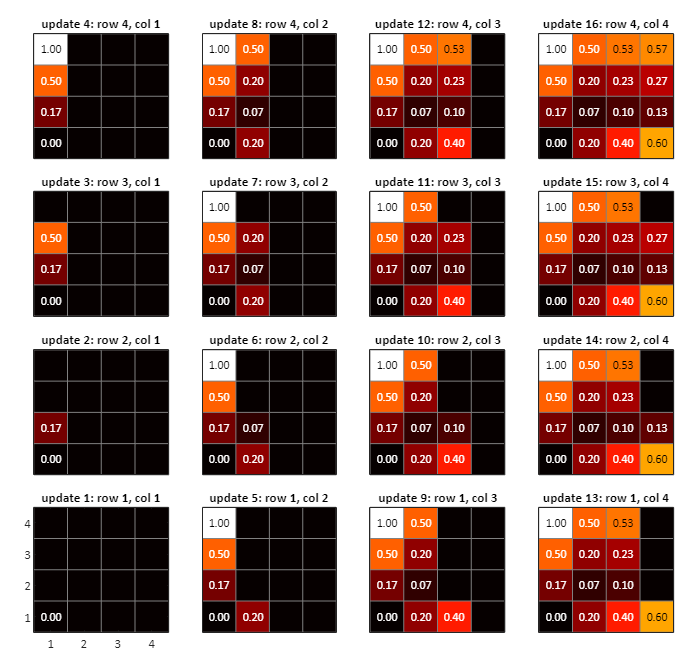

%first four samples of signals
x1 = X1(1:4);
x2 = X2(1:4);

%local distance matrix
lm = sqrt((x1'-x2).^2); 

steps = select_step_pattern('symmetric2');

[gcm,updates] = globalCostMatrix_algorithm(lm,steps);

plot_costmatrix_updates(updates);

For example, at update #6 (row 2, column 2), the costs of starting points for each of three allowed step patterns (repeated below) are the current values of the global cost matrix:

- starting cost for the horizontal step: value of cost matrix at row 2, column 1: $0.17$

- starting cost for the vertical step: value of cost matrix at row 1, column 2: $0.20$

- starting cost for the diagonal step: value of cost matrix at row 1, column 1: $0.0$

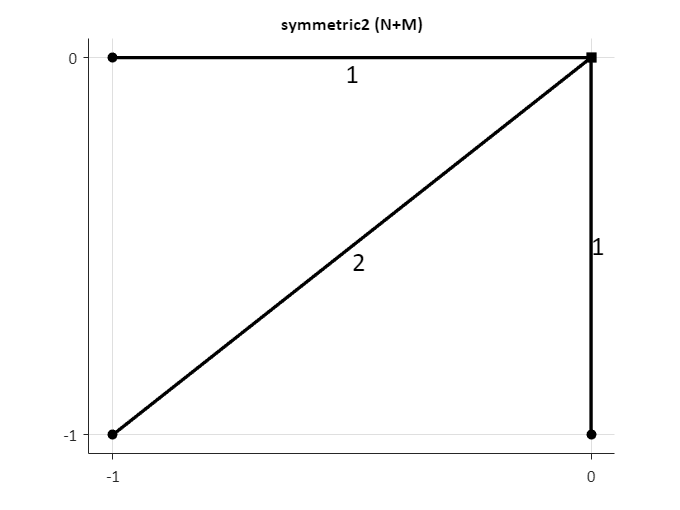

plot_steps(steps);


costs = updates(6).costs

costs =     0.0667
    0.2000
    0.2333


For each step pattern, the total cost is determined by looping over its component segments and adding the cost of each segment (segment cost $\times$ local distance) to the starting cost. In this case (update #6), the step pattern with the minimum total cost is the first one (the diagonal step pattern). 

The lowest cost step pattern (to move to each cell) of the global cost matrix is recorded in another matrix, a "steps matrix" shown below. Notice that there is no value for the starting cell (lower left corner) because the algorithm begins here.

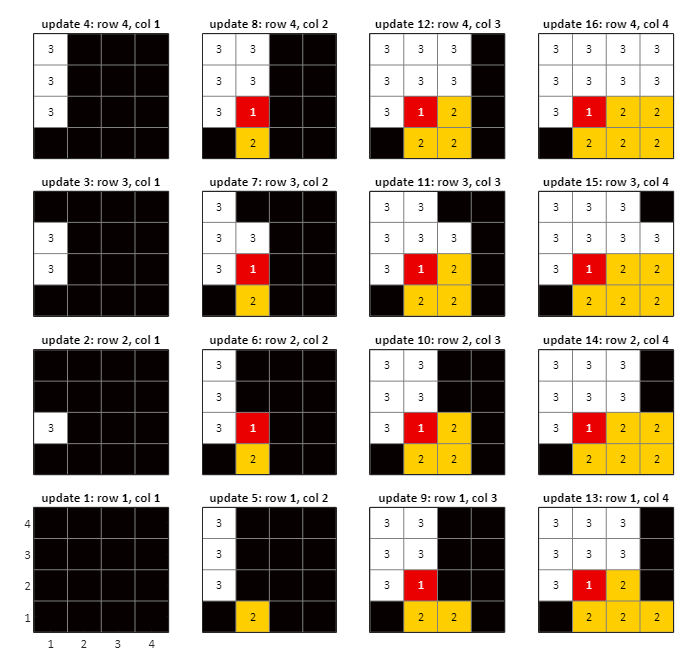

plot_costmatrix_updates(updates,'steps');

#### Backtracking

The warping path (time index map) is determined by a backtracking algorithm which starts at the last cell of the steps matrix collects the sample indices (of the original signals) which correspond to the selected step. The algorithm then moves to the cell specified by the 

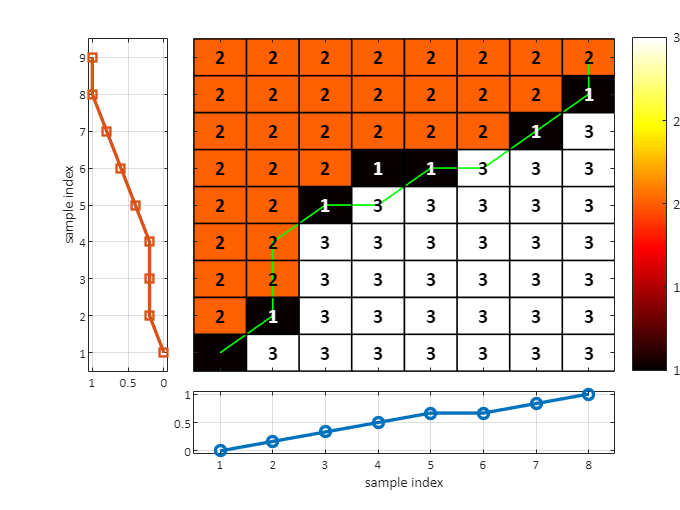

plot_matrix_path(info,X1,X2,'directionMatrix');

## Global windows

Global windows impose limits on the distance between samples in the dtwm map. 

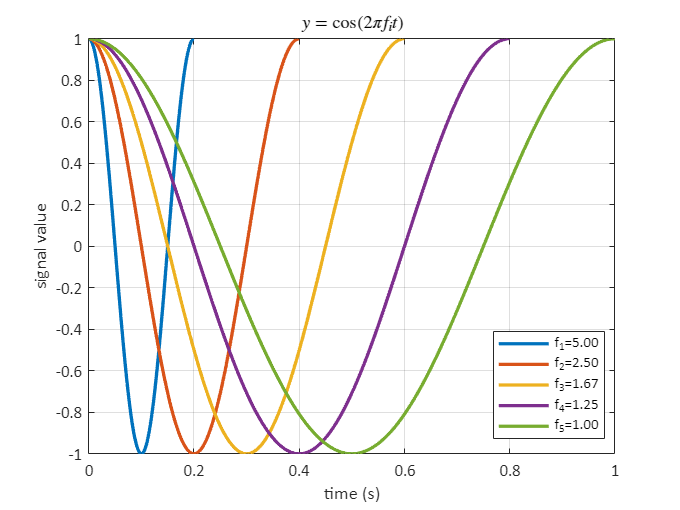

s = test_signals('cos_freq_var');
plot_signals(s);


x1 = s.X{4};
x2 = s.X{5};

window_types = {'','sakoechiba','itakura','slantedband'};
window_args = {[],500,[],500};

for i=1:length(window_types)
    [wcurves{i},distances(i),infos{i}] = dtwm(x1,x2, ...
    'window_type',window_types{i},'window_args',window_args{i});
end


Four types of global windows are implemented in `dtwm.` These are shown with global cost matrices below. The gray areas are mappings between signal indices that are disallowed.

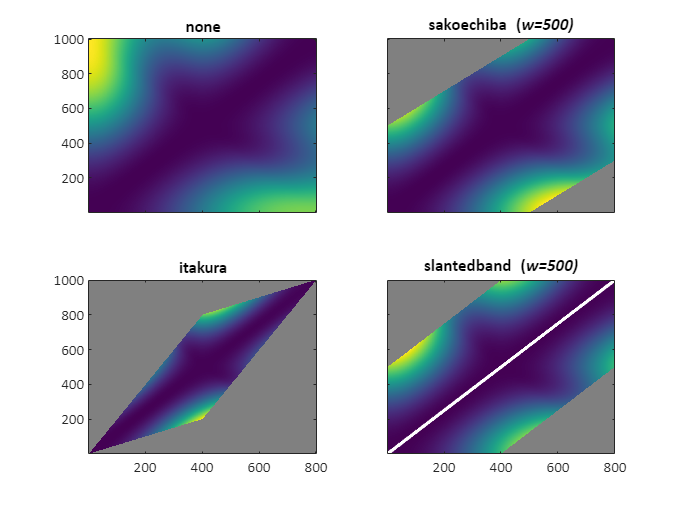

plot_global_windows(wcurves,infos);

The Sakoe-Chiba window is defined by the following equation, where $w$ is a window size parameter, $i$ and $j$ are the samples indices of the signals, and $\mathrm{I_{ij}}$ is a logical matrix indicating whether a mapping between samples $i$ and $j$ is allowed:

    
$$\mathrm{I_{ij}}=|j-i|\le w$$


The Itakura window is defined by the following equation, where $m$ and $n$ are the lengths of the signals indexed by $j$ and $i$, respectively:

    
$$\mathrm{I_{ij}}=(j-1<2(i-1)) \land (i-1\le 2(j-1)) \land (i\ge n-1-2(m-(j-1) \land (j>m-1-2(n-(i-1)))$$


The "$\land$" symbol is logical `AND` in the above equation. Note that there are no parameters in this window. Intuitively, the window  imposes the condition that the signals are well-aligned at their beginnings and ends, but may be less closely aligned in-between. This can be seen in the example above.

The slanted-band window is defined by the following equation, where $w$ is a window size parameter, and $m$ and $n$ are the lengths of the signals indexed by $j$ and $i$, respectively:

    
$$\mathrm{I_{ij}}=\left|j-i\left(\frac{ m}{n}\right)\right|\le w$$


Note that this is similar to the Sakoe-Chiba window, except that the constraint involves the distance between sample $j$ and a scaled value of sample $i$. The factor $\frac{m}{n}$ basically converts the value of sample index $i$ to the scale of sample $j$.

One important point to make about the Sakoe-Chiba band is that when the absolute value of the difference in signal lengths is greater than the window, i.e. $|n-m|>w$, there is no solution for global alignment. For instance, consider the signals below:

plot_signals(s);

Here is the matrix of distances obtained between each pair of signals. Notice that some of the pairs do not have a distance, and `dtwm` returns an error in these cases. Note that `dtwm_pairwise` is a wrapper for `dtwm` that calculates all pairwise warping curves between the signals in an input cell array:

[wcurves,distances,infos] = dtwm_pairwise(s.X, ...
    'window_type','sakoechiba', ...
    'window_args',500);

error: no warping path found compatible with the local constraints
error: no warping path found compatible with the local constraints
error: no warping path found compatible with the local constraints
error: no warping path found compatible with the local constraints
error: no warping path found compatible with the local constraints
error: no warping path found compatible with the local constraints


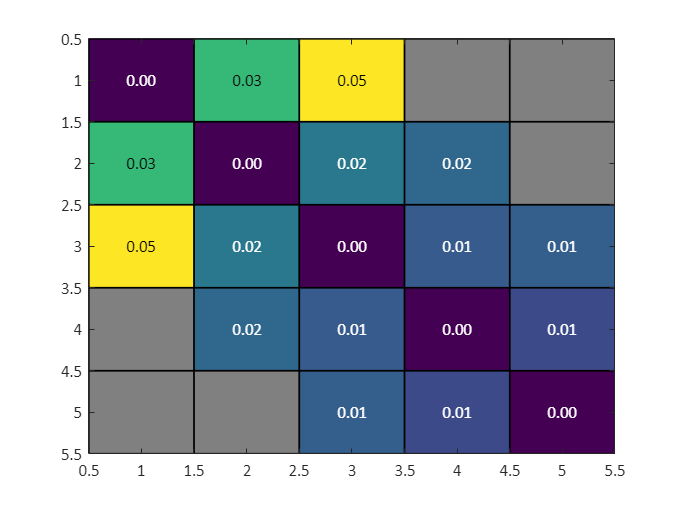


fig; stf_matrix(10*distances);

The reason can be seen in the windowed cost matrix, shown below for signals 1 and 4: the Sakoe-Chiba window excludes the last 100 samples of signal 4, since their indices are more than $500$ samples greater than the length of the signal 1:

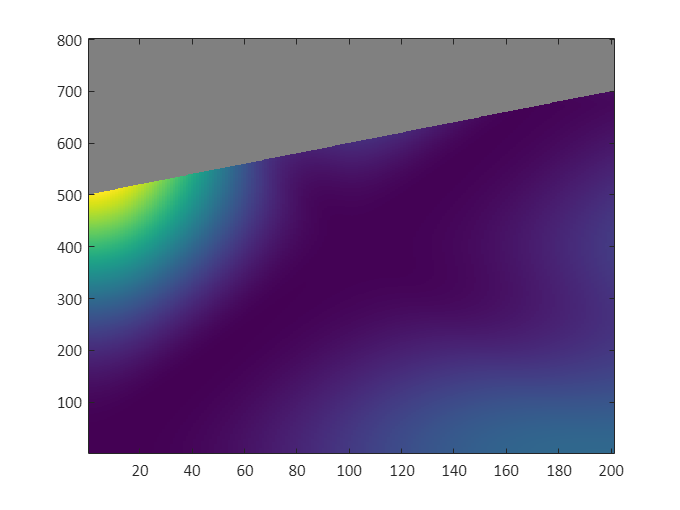

plot_global_windows(wcurves(1,4),infos(1,4));

Note that this issue does not arise for slanted band, as evidenced by the distance matrix below. Nor does arise for Itakura (not shown):

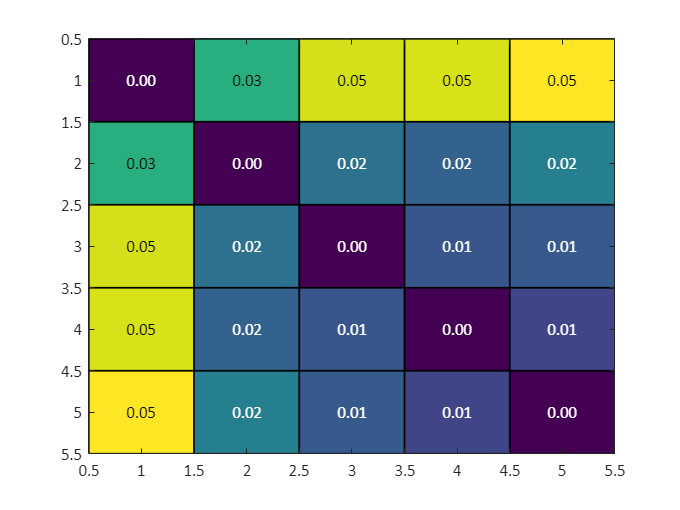

[wcurves,distances,infos] = dtwm_pairwise(s.X, ...
    'window_type','slantedband', ...
    'window_args',500);

fig; stf_matrix(10*distances);

## Unconstrained endpoints

Partial matching can be accomplished by calling `dtwm` with the parameters `open_end` and/or `open_begin` set to `true`. 

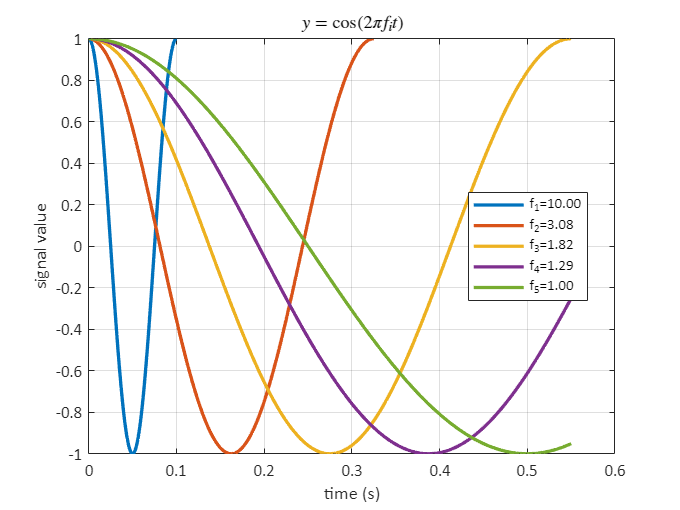

s = test_signals('cos_freq_var_trunc');
plot_signals(s);

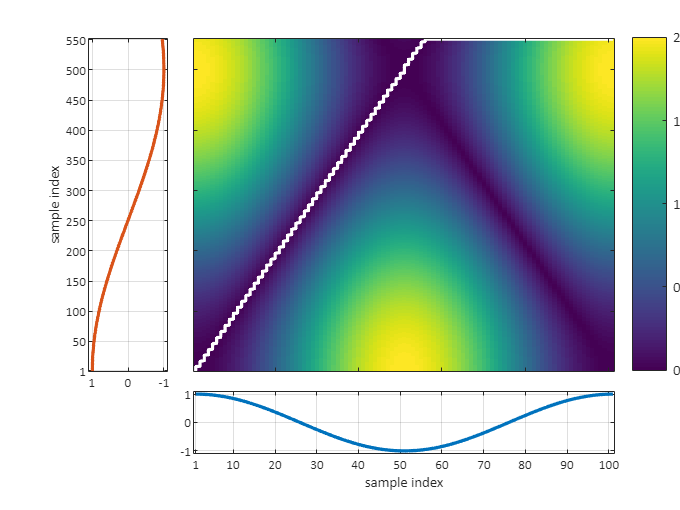

[wcurves,distances,infos] = dtwm_pairwise(s.X,'open_end',true);

ix = [1 5];

plot_matrix_path(infos{ix(1),ix(2)},s.X{ix(1)},s.X{ix(2)});

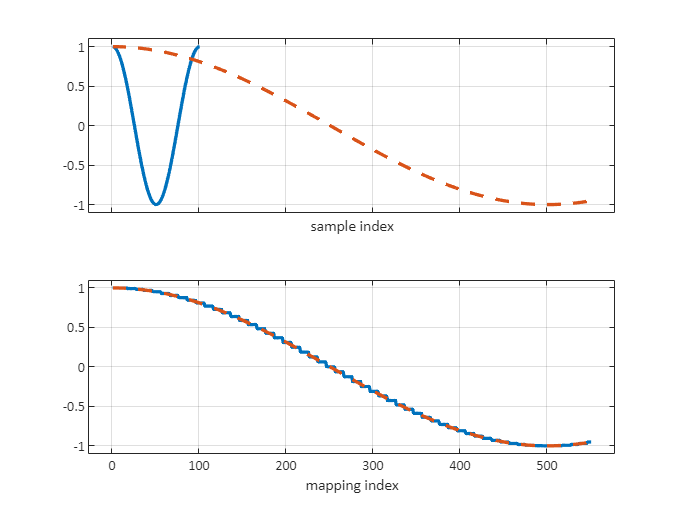

X1 = s.X{ix(1)};
X2 = s.X{ix(2)};

X1a = X1(wcurves{ix(1),ix(2)}(1,:));
X2a = X2(wcurves{ix(1),ix(2)}(2,:));

alignment_comparison(X1,X2,X1a,X2a);

## Testing and validation of dtwm by comparison to dtw-python

The successful compilation of the mex file `dtwm_costmatrix` can be tested by:

Building with 'Microsoft Visual C++ 2019 (C)'.
MEX completed successfully.
Elapsed time is 0.140527 seconds.


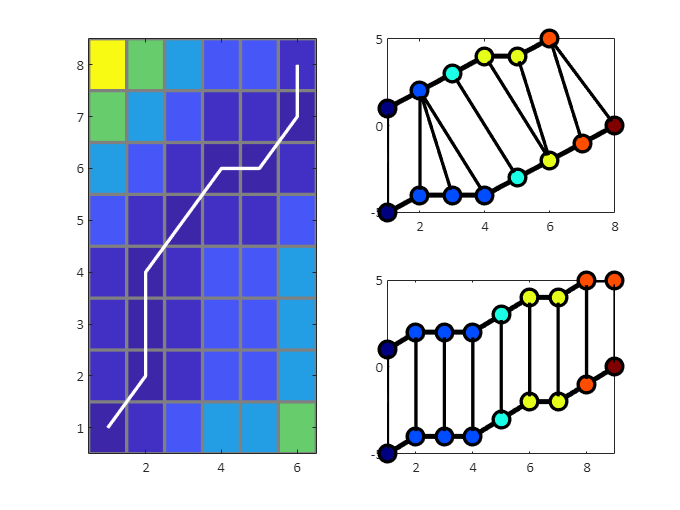

dtwm_test

If this function is not compiled successfully, dtwm can be called with the 'use_mex' parameter set to false:


%test signals
x = [1 2 3 4 4 5]; 
y = [1 2 2 2 3 4 5 6];

tic
dtwm(x,y,'use_mex',false);
toc

Elapsed time is 0.044029 seconds.


Most of the step patterns and also the open end/begin options have been validated against the output of the dtw-python package (Giorgino, 2009). All of the code and data for validation is located in the toolbox subdirectory `./validation`. Assuming that the dtw-python package is installed, one can run the python script `dtw_validate.py, `which reads some example signals from the file `validation_signals`, and outputs warping curves in the file `validation_dtwpython_output`. The dtw-python output can then be compared with the output of `dtwm` with the following script:

addpath('validation');
dtwm_validate;

Elapsed time is 0.974242 seconds.
         pattern         passed
    _________________    ______

    {'symmetric1'   }    true  
    {'symmetric2'   }    true  
    {'asymmetric'   }    true  
    {'symmetricP0'  }    true  
    {'asymmetricP0' }    true  
    {'symmetricP05' }    true  
    {'asymmetricP05'}    true  
    {'symmetricP1'  }    true  
    {'asymmetricP1' }    true  
    {'symmetricP2'  }    true  
    {'asymmetricP2' }    true  
    {'typeIa'       }    true  
    {'typeIb'       }    true  
    {'typeIc'       }    true  
    {'typeId'       }    true  
    {'typeIas'      }    true  
    {'typeIbs'      }    true  
    {'typeIcs'      }    true  
    {'typeIds'      }    true  
    {'typeIIa'      }    true  
    {'typeIIb'      }    true  
    {'typeIIc'      }    true  
    {'typeIId'      }    true  
    {'typeIIIc'     }    true  
    {'typeIVc'      }    true  



function [] = fig()
clear all; %#ok<CLALL> 
set(0,'defaultfigureposition',[ 680   558   560   420],'defaultfigureunits','pixels');
set(0,'defaultlinelinewidth',2);
figure('units','pixels','position',[ 680   558   560   420]);
end

%% for plotting signals
function [ph] = plot_signals(S)
fig;
if length(S.X{1})<50
    linespec = 'o-';
else
    linespec = '-';
end
for i=1:length(S.X)
    ph(i) = plot(S.t{i},S.X{i},linespec); hold on;
end
title(S.formula,'Interpreter','latex');
xlabel('time (s)');
ylabel('signal value');
legend(ph,S.labels,'location','best');
set(gca,'XGrid','on','YGrid','on');
end

%% for plotting cost matrices and paths
function [] = plot_matrix_path(mapinfo,x1,x2,varargin)
fig;
ax = gca;

params = {};
if length(x1)<50
    params = {'signals_linespec',{'o-','s-'},...
        'path_linespec','o-','matrixgrid',true};
end


if isempty(varargin)
    h = plot_dtw_matrix(mapinfo,x1,x2,'parent',ax,params{:});
else
    switch(varargin{1})
        case 'localcost'
            h = plot_dtw_matrix(mapinfo,x1,x2,'parent',ax,params{:});

        case 'globalcost'
            h = plot_dtw_matrix(mapinfo,x1,x2,'parent',ax,params{:},...
                'matrixfield','costMatrix','colormap',flipud(gray(100)),...
                'path_linecolor','g','showvalues',true);
            h.maph.LineWidth = 1;
            h.maph.Marker = 'none';    

        case 'directionMatrix'
            h = plot_dtw_matrix(mapinfo,x1,x2,'parent',ax,params{:},...
                'matrixfield','directionMatrix','colormap',hot(100),...
                'path_linecolor','g','showvalues',true,'formatstr','%1.0f', ...
                'fontsize',12,'fontcolor',[0 0 0],'fontweight','bold');
            h.maph.LineWidth = 1;
            h.maph.Marker = 'none';              
    end
end

end

%% for plotting mappings
function [] = plot_mapping(map)
fig;
h = plot_time_map(map,'label_mappings',true);
end

%% comparison of alignments
function [] = alignment_comparison(x1,x2,x1a,x2a)
if length(x1)<50
    linespec = {'o-','s--'};
else
    linespec = {'-','--'};
end
fig;
ax(1) = subplot(2,1,1);
ax(2) = subplot(2,1,2);

axes(ax(1));
plot(x1,linespec{1}); hold on;
plot(x2,linespec{2}); 
axes(ax(2));
plot(x1a,linespec{1}); hold on;
plot(x2a,linespec{2});
axis(ax,'tight');
set(ax,'XGrid','on','YGrid','on');

xlabel(ax(1),'sample index');
xlabel(ax(2),'mapping index');

ylims = ylim(ax(1));
ylim(ax,ylims+0.05*diff(ylims)*[-1 1]);

xlims = minmax([xlim(ax(1)) xlim(ax(2))]);
xlim(ax,xlims+0.05*diff(xlims)*[-1 1]);

set(ax(1),'XTickLabel',[]);

Nmax = max(cellfun(@(c)length(c),{x1,x2,x1a,x2a}));

if length(x1)<20
    set(ax,'XTick',1:Nmax);
end

end

%% plot step patterns
function [h] = plot_steps(pat,varargin)

if istable(pat)
    pat = table2struct(pat);
end

if numel(pat)==1
    fig;
    h= plot_step_pattern(pat,'parent',gca);
else
    axgrid = stf_axes_grid(numel(pat),'mincols',min(numel(pat),3));
    ax = stf(axgrid,...
        [0.05 0.10 0.01 0.10],[0.05 0.10],'aspect',3/min(size(axgrid,1),3));
    for i=1:length(pat)
        h{i} = plot_step_pattern(pat(i),'parent',ax(i),'fontsize',8,'linewidth',1);
    end
end
end

%% plots global window examples
function [] = plot_global_windows(maps,map_infos)



switch(numel(maps))
    case 4
        fig;
        ax(1) = subplot(2,2,1);
        ax(2) = subplot(2,2,2);
        ax(3) = subplot(2,2,3);
        ax(4) = subplot(2,2,4);
        title_strs = {'none',...
            ['sakoechiba ({{\it}w}=' num2str(map_infos{2}.windowArgs) ')'],...
            'itakura',...
            ['slantedband ({{\it}w}=' num2str(map_infos{4}.windowArgs) ')']};
    otherwise
        fig;
        ax = gca;
        title_strs = {''};
end



for i=1:length(ax)
    stf_matrix(map_infos{i}.costMatrix','textvalues',false, ...
        'gridlines',false,'ydir','normal','parent',ax(i));

    if ~isempty(maps{i})
        plot(maps{i}(1,:),maps{i}(2,:),'w-');
    end

    title(ax(i),title_strs{i});
end

switch(numel(maps))
    case 4
        set(ax([2 4]),'YTickLabel',[]);
        set(ax([1 2]),'XTickLabel',[]);
end

end


%% plots updates of cost matrix algorithm
function [] = plot_costmatrix_updates(updates,varargin)
L = size(updates,1);

axpan = flipud(reshape(1:numel(updates),L,[]));
ax = stf(axpan,[0.05 0.05 0.01 0.05],[0.05 0.05],'aspect',1);

plot_var = 'cm';
format_str = '%1.02f';
if ~isempty(varargin) && strcmp(varargin{1},'steps')
    plot_var = 'dm';
    format_str = '%1.0f';
end

max_cost = max([updates.(plot_var)],[],'all');

for i=1:length(ax)
    axes(ax(i));
    im(i) = imagesc(updates(i).(plot_var)); hold on;
    title(sprintf('update %i: row %i, col %i',i,updates(i).row,updates(i).col),...
        'fontsize',8);
    stfig_gridlines('xy','linewidth',0.5,'color',0.5*ones(1,3));
    matrix_text(updates(i).(plot_var),...
        'fontcolor',[1 1 1; 0 0 0],'color_threshold',0.5*max_cost,...
        'fontsize',7,'formatstr',format_str);
end
set(ax,'YDir','normal');
set(ax(2:end),'XTick',[],'YTick',[]);
set(ax,'colormap',hot(100),'CLim',[0 max_cost]);
set(ax(1),'XTick',1:L,'YTick',1:L)
end